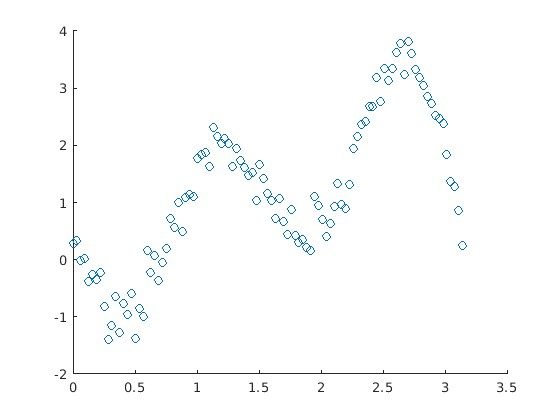

data=readtable("data1");
X=table2array(data(:,1));
Y=table2array(data(:,2));
scatter(X,Y)

XX=0:0.01:3.3;
e = @(x) ones(size(x))

e = function_handle with value:
    @(x)ones(size(x))


f = @(x) sin(x);
g = @(x) sin(2*x);
h = @(x) sin(3*x);
j = @(x) sin(4*x);

A=[e(X),f(X),g(X),h(X),j(X)];
c=A\Y

c =     0.5174
    0.9287
   -1.0071
    0.3587
   -1.4822


h=@(x) e(x)*c(1)+c(2)*f(x)+c(3)*g(x)+c(4)*h(x)+c(5)*j(x);
YY=h(XX)

YY =     0.5174    0.4581    0.3988    0.3397    0.2809    0.2225    0.1645    0.1070    0.0502   -0.0059   -0.0611   -0.1155   -0.1689   -0.2212   -0.2724   -0.3223   -0.3709   -0.4182   -0.4640   -0.5083   -0.5510   -0.5920   -0.6313   -0.6689   -0.7046   -0.7384   -0.7702   -0.8001   -0.8279   -0.8537   -0.8773   -0.8987   -0.9180   -0.9351   -0.9499   -0.9624   -0.9727   -0.9806   -0.9863   -0.9896   -0.9906   -0.9893   -0.9857   -0.9798   -0.9715   -0.9610   -0.9482   -0.9331   -0.9159   -0.8964


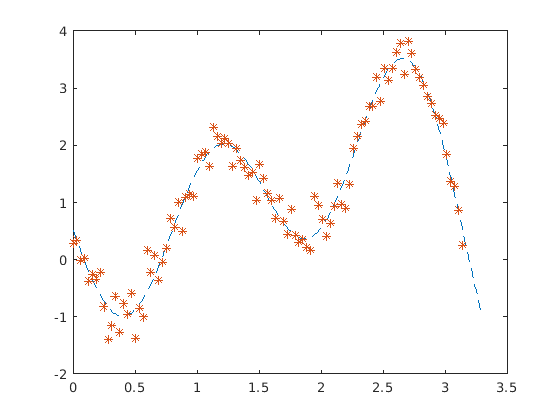

plot(XX,YY,'--',X,Y,'*')